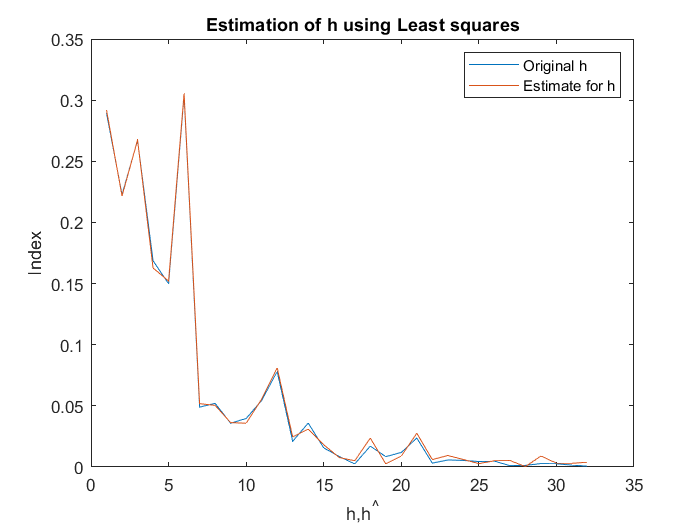

clc;
clear all;
close all;
% Initialize
n_ele=512;
L=32;
lambda=0.2;
a=mvnrnd(zeros(L,1),1/2);
b=mvnrnd(zeros(L,1),1/2);
% n~cn(0,1)
nr=mvnrnd(zeros(n_ele,1),.01);
ni=mvnrnd(zeros(n_ele,1),.01);
n=nr+1i*ni;
% random data 512 samples
data=randi([0 3],n_ele,1);
%Mod Demod
QPSKModulator = comm.QPSKModulator;
QPSKDemodulator = comm.QPSKDemodulator;
%QPSK Modulation
Sym = QPSKModulator(data)*sqrt(2);
% X
X=diag(Sym);
k=1:L;
j=1:n_ele;
% Generate P
p=exp(-lambda.*(k'-1));
pnorm=norm(p);
%Generate h[k]
h=(a+1i.*b).*p./pnorm;
%Generate F mat [512*L] IDFT
F=zeros(n_ele,L);
F(j,k)=exp(2.*pi.*1i.*((j-1)'*(k-1))./n_ele);
H=X*F;
% Obtain y
y=X*F*h+n;
%Estimate h
h_hat= (H'*H)\(H')*y;
plot(abs(h));title('Estimation of h using Least squares')
hold on
plot(abs(h_hat));xlabel('h,h^\^');ylabel('Index')%title('h^\^')
legend('Original h','Estimate for h')

Jmin_1=(norm(y-H*h_hat)).^2

Jmin_1 = 9.9693


%Q2
NonZeros=[1 2 3 4 5 6]; %let
h2=zeros(size(h));
h2(NonZeros,:)=h(NonZeros,:);
y2=H*h2 + n;
H2=H(:,NonZeros);
h_hat2=inv(H2'*H2)*H2'*y2;
h_hat22=zeros(size(h));
h_hat22(NonZeros,:)=h_hat2;
Jmin2=norm(y2-H2*h_hat2).^2

Jmin2 = 10.5758

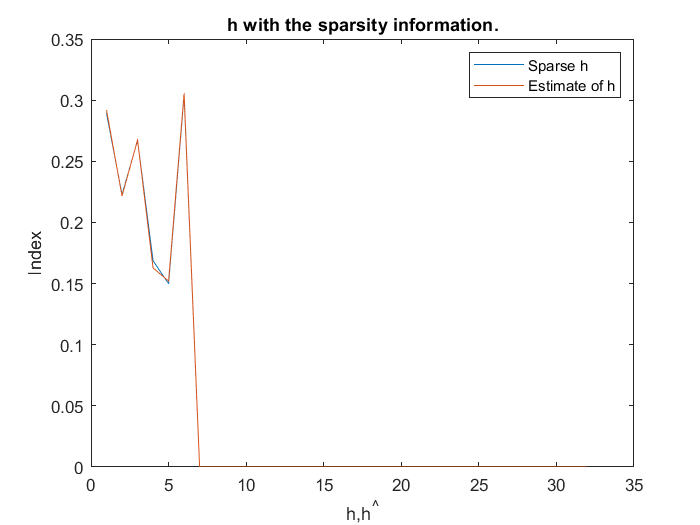

figure;
plot(abs(h2));title('h with the sparsity information.');xlabel('h,h^\^');ylabel('Index')
hold on
plot(abs(h_hat22));
legend('Sparse h','Estimate of h')


%Q3a
alpha1 = 1;%let
X3=X;
X3(1:180,1:180)=0;
X3(end-179:end,end-179:end)=0;
y3=X3*F*h + n;
H3=X3*F;
%(H3'*H3) is badly scaled
HTH=H3'*H3 + alpha1*eye(size(H3,2)); %if alpha1 = 0, Matrix is close to singularity
h_hat3=inv(HTH)*H3'*y3;
Jmin3=norm(y3-H3*h_hat3).^2

Jmin3 = 10.4280

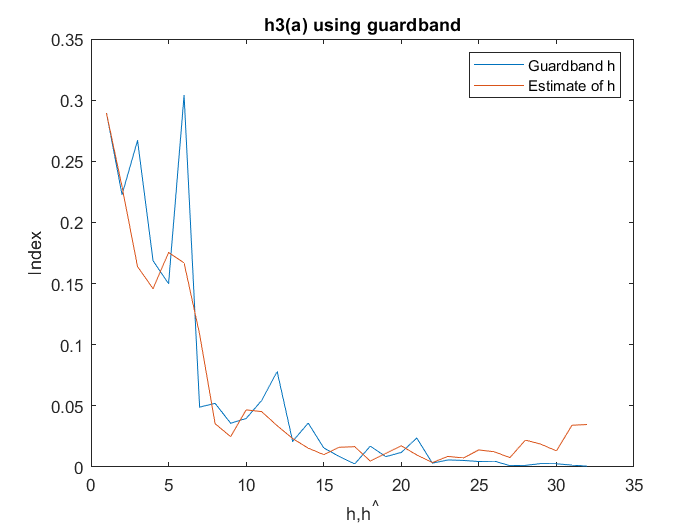

figure;
plot(abs(h));title('h3(a) using guardband');xlabel('h,h^\^');ylabel('Index')
hold on
plot(abs(h_hat3));%title('h^\^')
legend('Guardband h','Estimate of h')

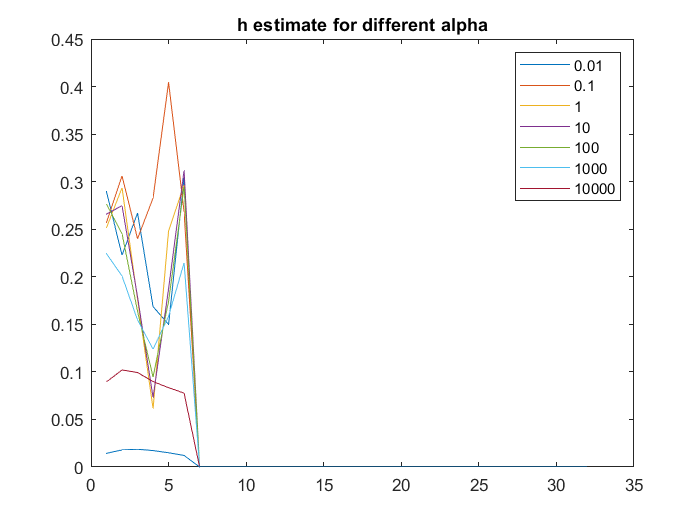

%3)b
figure;
plot(abs(h2));title('h estimate for different alpha')
hold on
alpha2=0.01;
for j=1:7
    alpha1(j)=alpha2;
H3b=X3*F;
y3b(:,j)=H3b*h2 + n;
H2=H3b(:,NonZeros);
h_hat_inv3b=inv(H2'*H2+alpha2*eye(6,6))*H2'*y3b(:,j);
h_hat_est3b=zeros(size(h));
h_hat_est3b(NonZeros,:)=h_hat_inv3b;
Jmin3b(j)=norm(y3b(:,j)-H2*h_hat_inv3b).^2;
plot(abs(h_hat_est3b))
h_hat_est_3b_mat(:,j)=h_hat_est3b;
alpha2=alpha2*10;
end
alpha_val=string(alpha1);
legend(alpha_val);

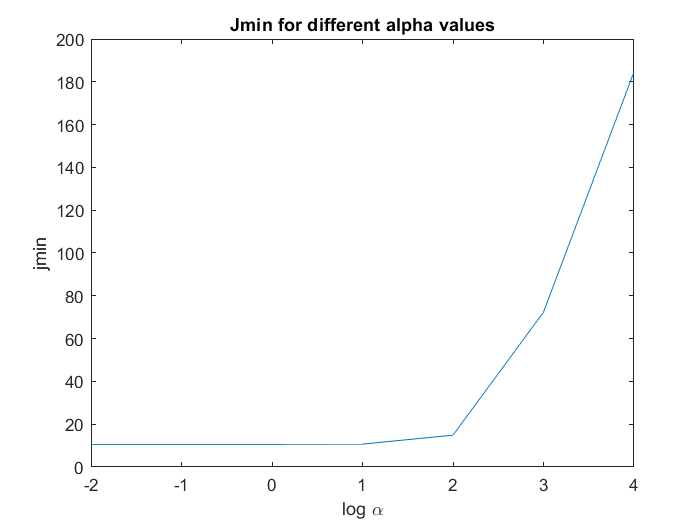

figure;
plot(log10(alpha1),Jmin3b);ylabel('jmin');xlabel('log \alpha')
title('Jmin for different alpha values')

Jmin3b_mean=mean(Jmin3b);

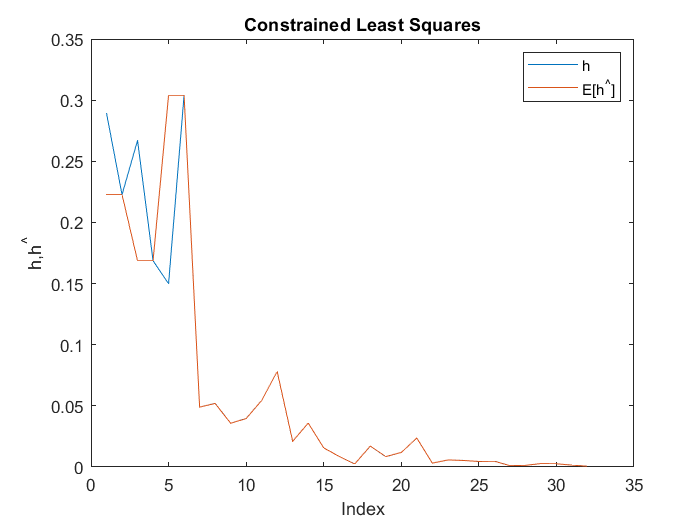



%Q4
% h1= h2
% h3= h4
% h5= h6

% Formulate A matrix & b st Ax= b
A=[1,-1,0,0,0,0;0,0,1,-1,0,0;0,0,0,0,1,-1];
A_zeros=zeros(3,26);
A=[A A_zeros];
b=zeros(3,1);
iterations=10000;% let
Jmin=zeros(1,iterations);
h_hat_mat=zeros(32,iterations);
h1=h;
h1(1)=h1(2);
h1(3)=h1(4);
h1(5)=h1(6);
 estimated_mse=0;
for runs=1:iterations
    data=randi([0 3],n_ele,1);
    Sym = QPSKModulator(data)*sqrt(2);
    X4=diag(Sym);
    H4=X4*F;
    nr=mvnrnd(zeros(n_ele,1),.01);%variance {0.1,0.01}
    ni=mvnrnd(zeros(n_ele,1),.01);
    n=nr+1i*ni;
    
    y4=X4*F*h1+n;
    %Estimate for unconstrained h
    h_hat= (H4'*H4)\(H4')*y4;
    % lambda/2
    lambda_by2=inv(A*inv(H4'*H4)*A')*(A*h_hat-b);
    % estimate for constrained h
    h_hat_i=inv(H4'*H4)*A'*lambda_by2;
    h_hat4=h_hat-h_hat_i;
    Jmin(runs)=(norm(y4-H4*h_hat4)).^2;
    h_hat_mat(:,runs)=h_hat4;
    jmin4_theory(runs)=norm(n)^2;
    estimated_mse=estimated_mse + norm(h1-h_hat4).^2;
end
% E(h_hat)
h_hat4=mean(h_hat_mat,2);
figure;
plot(abs(h));
hold on
plot(abs(h_hat4));
title('Constrained Least Squares')
legend('h','E[h^\^]');ylabel('h,h^\^');xlabel('Index')

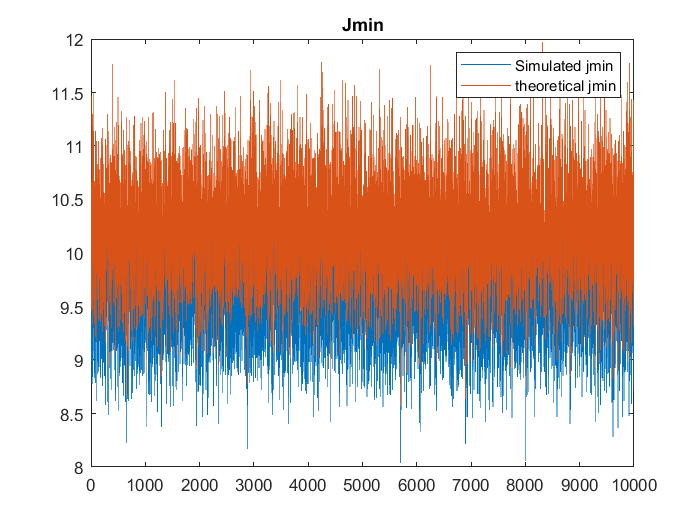

figure;
plot(Jmin);
title('Jmin')
hold on;
plot(jmin4_theory);
legend('Simulated jmin','theoretical jmin')

estimated_mse = estimated_mse./iterations

estimated_mse = 5.6664e-04

jmin4_theory_mean=mean(jmin4_theory)

jmin4_theory_mean = 10.2369

%%